clc;clear;close all

% PUMA560 manipulator collision avoidance demo
time_vec = linspace(0,3,100);
dt = time_vec(2) - time_vec(1); 

% load the PUMA560 robot 
puma560 = loadrobot("puma560");
joints = homeConfiguration(puma560);

% preallocations 
joint_pos = zeros(6,length(time_vec)); % system state 
joint_vel = zeros(6,length(time_vec)); % system input 
wrist_pos = zeros(3,length(time_vec)); % point of interest 

% assumes the robot has the following initial joint position and
% corresponding wrist position
joint_pos(:,1) = [0;0;0;0;0;0];  % rad
wrist_pos(:,1) = getWristPos(puma560,joints,joint_pos(:,1)); % m

% obstacle location 
pos_obs = [0;0.5;1.1090];  % m
R_obs = 0.1;          % m

% safety "bubble" around the robot wrist 
R_w = 0.1;            % m

% desired input (joint velocity)
u_des  = [1;0;0;0;0;0];  % rad/s

% gamma
gamma = 5; 

## computation loop


for i = 2:length(time_vec)

    % state and current wrist position 
    joint_pos_curr = joint_pos(:,i-1);
    wrist_pos_curr = wrist_pos(:,i-1);

    % apply CBF filter to compute safe vel. input
    % u_safe = u_des;
    u_safe = CBF_PUMA560(gamma,u_des,joints,joint_pos_curr,wrist_pos_curr,...
                         pos_obs,R_obs,R_w,puma560);
    joint_vel(:,i) = u_safe;

    % advance kinematics -> using the safe vel. input
    joint_pos(:,i) = joint_pos_curr + u_safe*dt;
    wrist_pos(:,i) = getWristPos(puma560,joints,joint_pos(:,i));

end 

## visualization loop

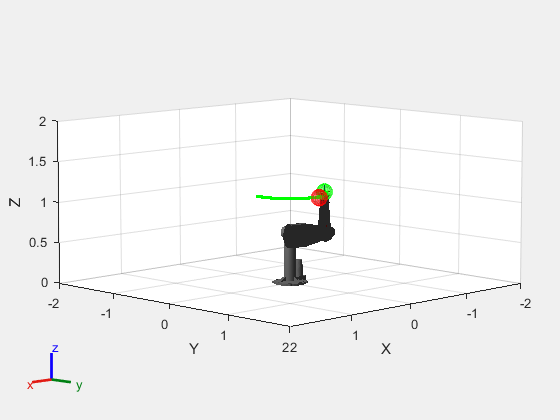

f = figure;
joints = updateJointStruct(joints,joint_pos(:,1));
robot_visual = show(puma560,joints,'FastUpdate',true,'PreservePlot',false);
hold on

[x_obs,y_obs,z_obs] = sphere;
x_obs = x_obs*R_obs; y_obs = y_obs*R_obs; z_obs = z_obs*R_obs;
[x_wrist,y_wrist,z_wrist] = sphere;
x_wrist = x_wrist*R_w; y_wrist = y_wrist*R_w; z_wrist = z_wrist*R_w;

surf(x_obs+pos_obs(1),y_obs+pos_obs(2),z_obs+pos_obs(3),...
     'FaceColor',[1 0 0],'EdgeColor',[1 0 0],'FaceAlpha',0.3,'EdgeAlpha',0.3);
wrist_visual = surf(x_wrist+wrist_pos(1,1),y_wrist+wrist_pos(2,1),z_wrist+wrist_pos(3,1),...
    'FaceColor', [0 1 0], 'EdgeColor',[0 1 0],'FaceAlpha',0.3,'EdgeAlpha',0.3);

axis([-2 2 -2 2 0 2])

waitforbuttonpress % press the keyboard

for i = 2:length(time_vec)
    joints = updateJointStruct(joints,joint_pos(:,i));
    robot_visual = show(puma560,joints,'FastUpdate',true,'PreservePlot',false);
    delete(wrist_visual)
    wrist_visual = surf(x_wrist+wrist_pos(1,i),y_wrist+wrist_pos(2,i),z_wrist+wrist_pos(3,i),...
        'FaceColor', [0 1 0], 'EdgeColor',[0 1 0],'FaceAlpha',0.3,'EdgeAlpha',0.3);
    plot3(wrist_pos(1,i),wrist_pos(2,i),wrist_pos(3,i),'g.');
    drawnow
    pause(0.01)
end 

## Plot first 3 joint velocities

f2 = figure

f2 =   Figure (6) with properties:

      Number: 6
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [680 458 560 420]
       Units: 'pixels'

  Show all properties


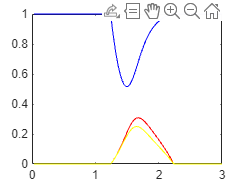

plot(time_vec(2:end),joint_vel(1,2:end),'b');
hold on
plot(time_vec(2:end),joint_vel(2,2:end),'r');
plot(time_vec(2:end),joint_vel(3,2:end),'y');

grid on 

## CBF

% CBF for PUMA 560 example -> Eqns (9) - (12)
function u_safe = CBF_PUMA560(gamma,u_des,joints,joint_pos_curr,wrist_pos_curr,...
                              pos_obs,R_obs,R_w,puma560)
    h = CBF_ballObs(wrist_pos_curr,pos_obs,R_obs,R_w);
    b = gamma*h;

    % get the robot jacobian
    joints = updateJointStruct(joints,joint_pos_curr);
    J = geometricJacobian(puma560,joints,"link7");

    % setup CBF constraints 
    A = -2*(wrist_pos_curr - pos_obs)'*J(4:6,:); % use only the linear velocity Jacobian
    H = 2*eye(6); f = -2*u_des;
    lb = -1*ones(6,1); ub = ones(6,1);
    Aeq = []; beq = []; uguess = zeros(6,1);
    options = optimoptions('quadprog','Algorithm','active-set','Display','none');
    u_safe  = quadprog(H,f,A,b,Aeq,beq,lb,ub,uguess,options);
end 

function h = CBF_ballObs(wrist_pos_curr,pos_obs,R_obs,R_w)
    h = norm(wrist_pos_curr - pos_obs)^2  - (R_obs + R_w)^2;   
end 

## Robot function

function wrist = getWristPos(puma560,joints,q)
    joints = updateJointStruct(joints,q);
    T = getTransform(puma560,joints,"link7","link1"); % forward kinematics 
    wrist = T(1:3,4);
end 

function joints = updateJointStruct(joints,q)
    for i = 1:length(q)
        joints(i).JointPosition = q(i);
    end 
end 